# Find critical densities in which digging begins and stops

load('Data\MeanData\MeanBinnedData.mat','S','M','t','varNames')
UseNests = [2:8 10:13 15:18 20:29];
t0 = find(t==0); tend = find(t==135);
t1 = t(t0:tend);


## Try out idea on Nest F4

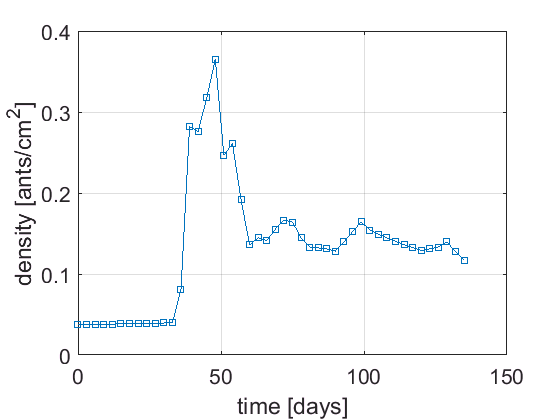

figure
k=4;
    fA = S(k).B.fArea(t0:tend);
    N = S(k).B.SmoothPop(t0:tend);
    density = N./fA;
    plot(t1,density,'-s')

grid on
xlabel('time [days]')
ylabel('density [ants/cm^2]')

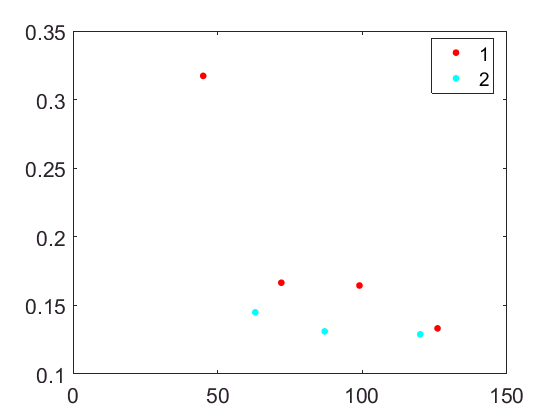

densityS = movmean(density,3); % smooth
[H_pks,H_locs] = findpeaks(densityS);
[L_pks,L_locs] = findpeaks(-densityS);

figure; % plig in detected smoothed peaks into non-smoothed time-series to get original peak values
gscatter(t1([H_locs;L_locs]),density([H_locs;L_locs]),[ones(numel(H_pks),1);2.*ones(numel(L_pks),1)])
xlim([0 150])

## Check on all nests

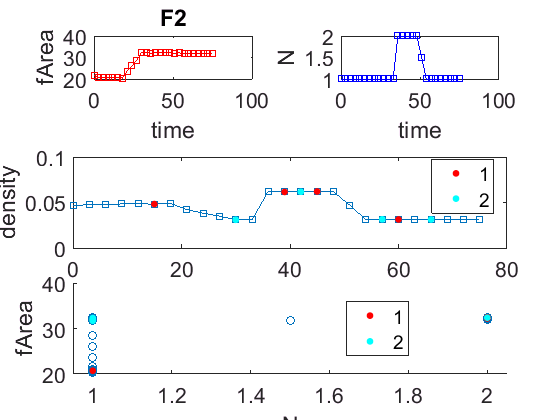

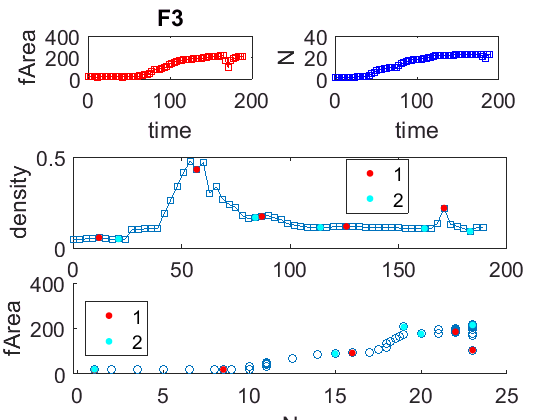

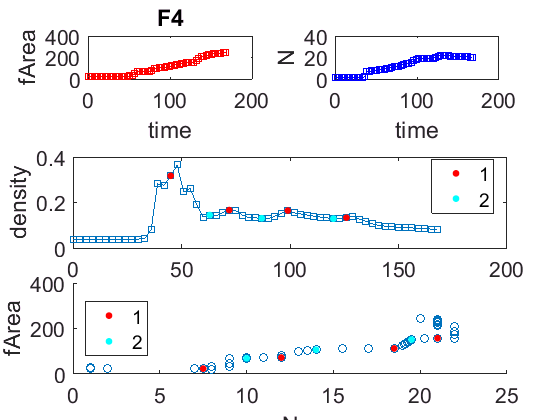

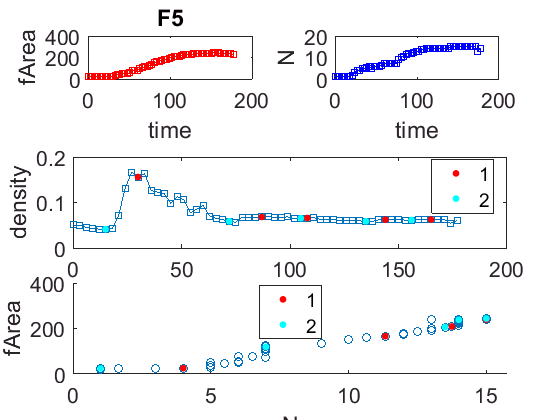

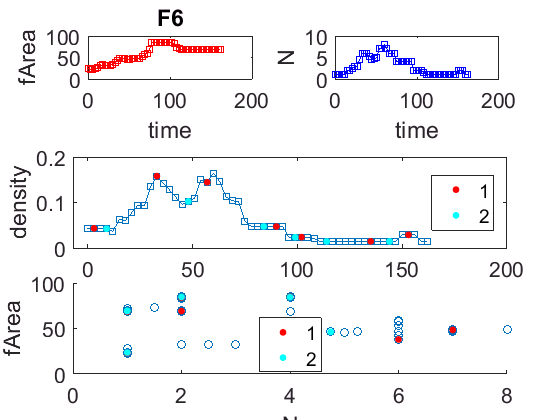

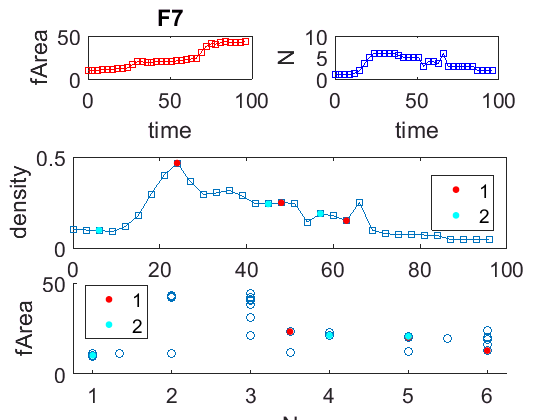

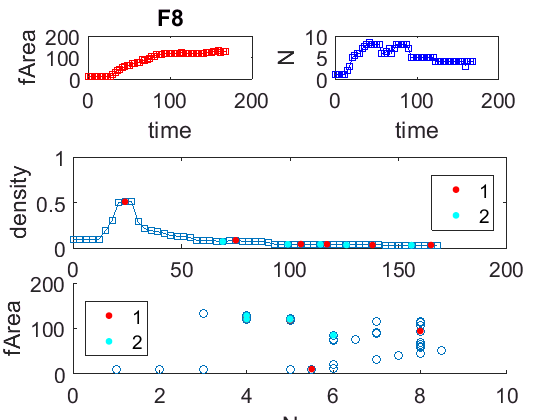

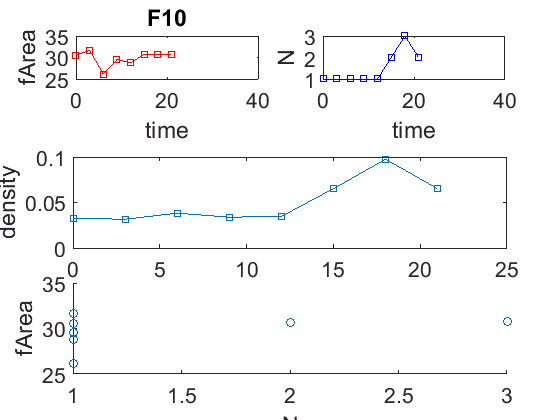

CritD = table;
Lags = table;
MeanDensities = nan(29,1);

for k=UseNests
    tend = find(~isnan(S(k).B.fArea),1,'last');
    t1 = t(t0:tend);
    fA = S(k).B.fArea(t0:tend);
    dAdt = diff(fA)./3;
    N = S(k).B.SmoothPop(t0:tend);
    density = N./fA;
    densityS = movmean(density,3); % smooth
    [H_pks,H_locs] = findpeaks(densityS);
    [L_pks,L_locs] = findpeaks(-densityS);
    
    % plot
    figure
    subplot(3,2,1)
    plot(t1,fA,'-sr')
    xlabel('time')
    ylabel('fArea')
   title(['F',num2str(k)])
    
    subplot(3,2,2)
    plot(t1,N,'-sb')
    xlabel('time')
    ylabel('N')
    
    subplot(3,2,3:4)
    plot(t1,density,'-s')
    xlabel('time')
    ylabel('density')
    
    

    
    T = table;
    T.tag = repmat(k,numel([H_locs;L_locs]),1);
    T.locs = [H_locs;L_locs];
    T.time = 3.*(T.locs-ones(height(T),1));
    T.density = density(T.locs);
    T.type = [ones(numel(H_locs),1);2.*ones(numel(L_locs),1)];
    T.fArea = fA(T.locs);
    T.N = N(T.locs);
    T.dAdt = dAdt(T.locs);
    
    hold on
    gscatter(T.time,T.density,T.type)
   
    subplot(3,2,5:6)
    scatter(N,fA)
    hold on
    gscatter(T.N,T.fArea,T.type)
    xlabel('N'); ylabel('fArea')
    
    % find lag between consecutive high -> low densities
    LagsNest = table;
    [timeline,I] = sort([H_locs;L_locs]);
    PKS = [H_pks;L_pks];
    PKS = PKS(I);
    TIMEdiff=[];
    RT = [];
    j=0;
    for i=2:numel(timeline)
        if i>1 && PKS(i)<0 && PKS(i-1)>0
            j=j+1;
            TIMEdiff(j)= 3.*(timeline(i)-timeline(i-1));
             % calc response time = time it takes to reach half of critical density low
            densityRT = densityS(timeline(i-1):timeline(i));
            densityRT = densityRT-repmat(densityRT(end),numel(densityRT),1);
            tRT = t1(timeline(i-1):timeline(i));
            RT(j) = tRT(find(densityRT<=0.5.*densityRT(1),1))-tRT(1);
        end
    end
    
    % mean stable value - average out the 2nd half of each density time-series
    MeanDensities(k) = mean(density(round(numel(density).*(2/3)):end));
    
    if isempty(TIMEdiff)
        continue
    end
    LagsNest.tag = repmat(k,j,1);
    LagsNest.lag = TIMEdiff';
    LagsNest.RT = RT';
% save  
    Lags = [Lags; LagsNest];
    CritD = [CritD; T];
    
end


MeanSA = mean(1./MeanDensities,'omitnan')

MeanDensity = 0.0998

SD_SA = std(1./MeanDensities,'omitnan')

SD_Density = 0.1188

## Plot histograms of results

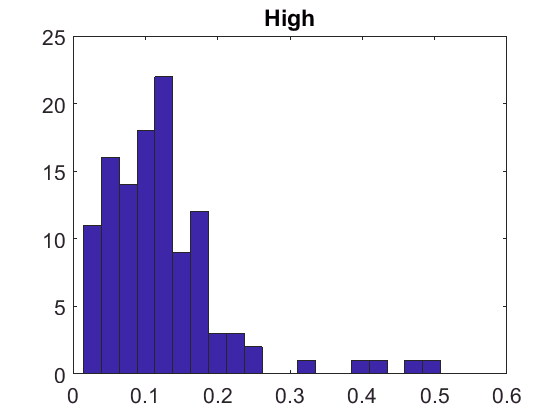

figure
hist(CritD.density(CritD.type==1),20)
title('High')

MeanHigh = mean(CritD.density(CritD.type==1))

MeanHigh = 0.1227

SDHigh = std(CritD.density(CritD.type==1))

SDHigh = 0.0844

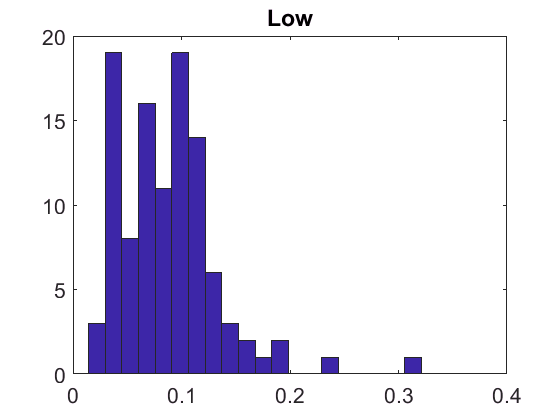


figure
hist(CritD.density(CritD.type==2),20)
title('Low')

MeanLow = mean(CritD.density(CritD.type==2))

MeanLow = 0.0878

SDLow = std(CritD.density(CritD.type==2))

SDLow = 0.0469

## Statistics

1st use Levene's test to check for equal variance between data

pL = 0.0015

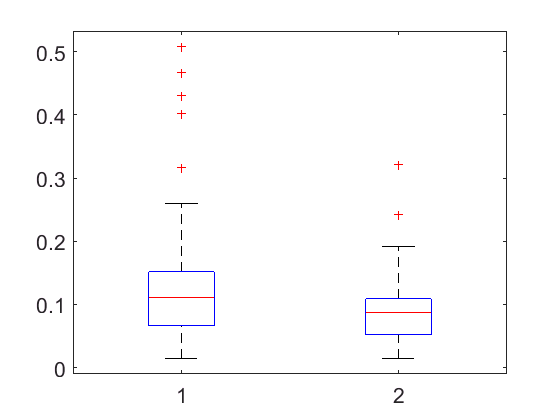

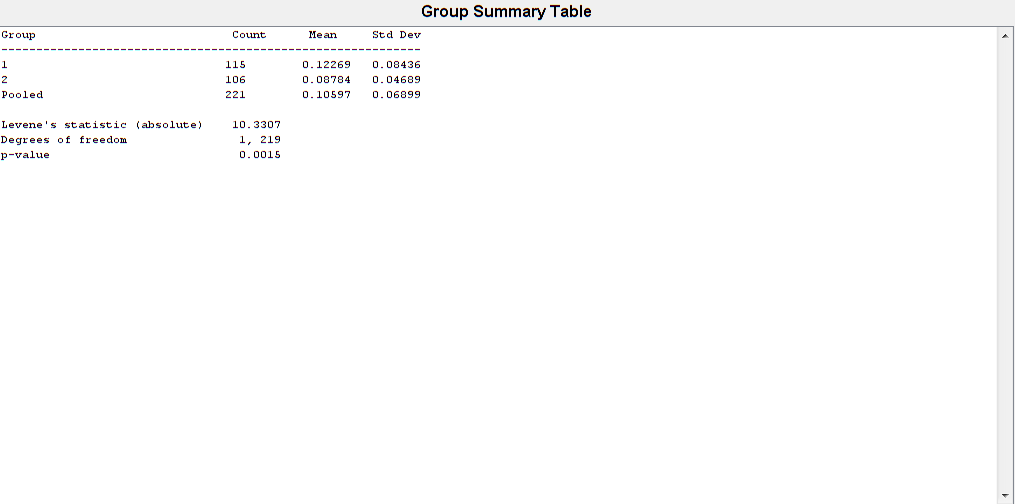

pL = vartestn(CritD.density,CritD.type,'TestType','LeveneAbsolute')

Get unequal variances

Run t-test between low and high values w/ unequal variances

[h,p,ci,stats] = ttest2(CritD.density(CritD.type==1),CritD.density(CritD.type==2),'Vartype','unequal')

h = 1

p = 1.7416e-04

ci =     0.0169
    0.0528

stats = struct with fields:
    tstat: 3.8335
       df: 181.1348
       sd: [2×1 double]

Got statistical difference 

but need to ANOVA as each set results are not independent (based on tag)

(problem with that variances are unequal)

p =     0.0000
    0.0000
    0.9828

tbl = 6×7 cell array
    'Source'    'Sum Sq.'    'd.f.'    'Singular?'    'Mean Sq.'    'F'          'Prob>F'    
    'X1'        [ 0.0694]    [   1]    [        0]    [  0.0694]    [17.7303]    [4.0858e-05]
    'X2'        [ 0.3210]    [  23]    [        0]    [  0.0140]    [ 3.5649]    [8.4822e-07]
    'X1*X2'     [ 0.0420]    [  23]    [        0]    [  0.0018]    [ 0.4669]    [    0.9828]
    'Error'     [ 0.6773]    [ 173]    [        0]    [  0.0039]           []              []
    'Total'     [ 1.1092]    [ 220]    [        0]            []           []              []

stats = struct with fields:
         source: 'anovan'
          resid: [221×1 double]
         coeffs: [75×1 double]
            Rtr: [48×48 double]
       rowbasis: [48×75 double]
            dfe: 173
            mse: 0.0039
    nullproject: [75×48 double]
          terms: [3×2 double]
        nlevels: [2×1 double]
     continuous: [0 0]
         vmeans: [2×1 double]
       termcols: [4×1 double]
     coeffnames: {75×1 cell}
           vars: [75×2 double]
       varnames: {2×1 cell}
       grpnames: {2×1 cell}
        vnested: []
            ems: []
          denom: []
        dfdenom: []
        msdenom: []
         varest: []
          varci: []
       txtdenom: []
         txtems: []
        rtnames: []

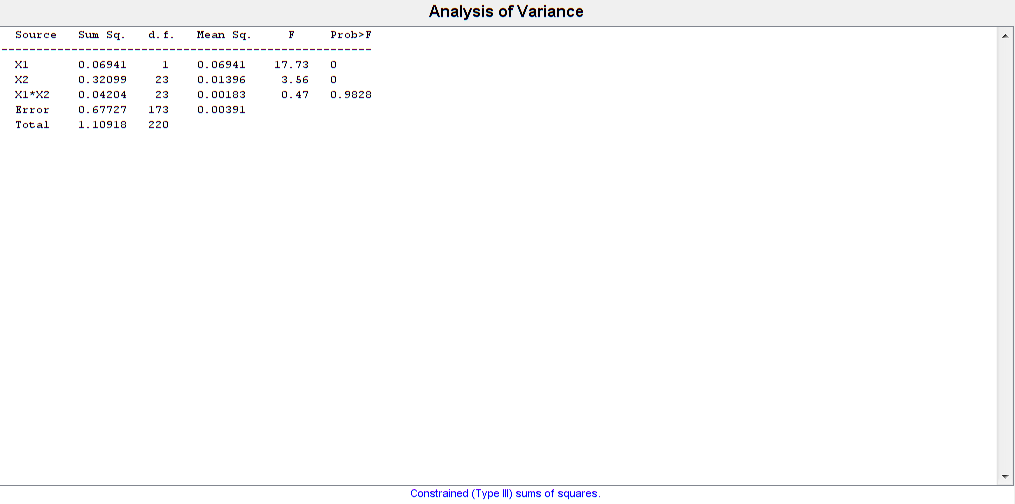



[p,tbl,stats] = anovan(CritD.density,{CritD.type,CritD.tag},'model','interaction')

***found using 2-way unbalanced ANOVA a significatnt difference between critical high and low densities regardless of specific experiment***

*test for normality of residuals*

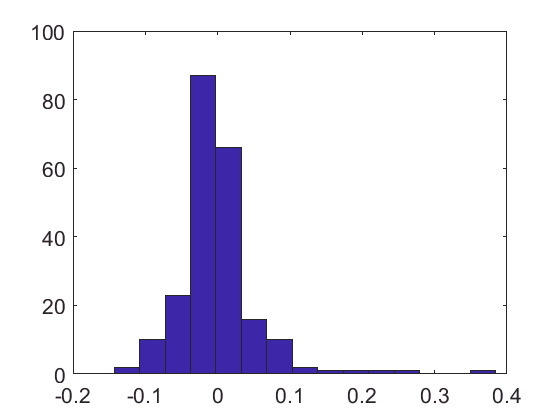

figure; hist(stats.resid,15)

residuals are normally distributed

## Look at time difference between consecutive high -> low densities

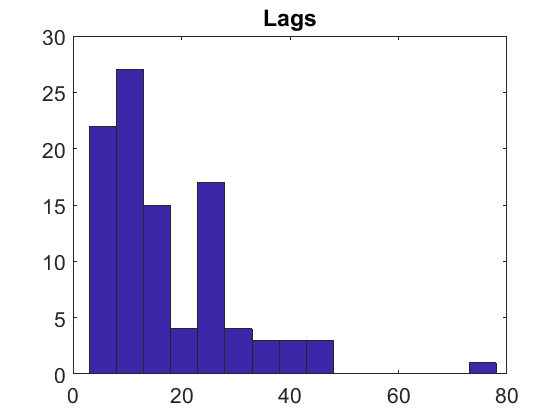

figure
hist(Lags.lag,15);
title('Lags')

MeanLags = mean(Lags.lag)

MeanLags = 17.1515

SDLags = std(Lags.lag)

SDLags = 12.7426

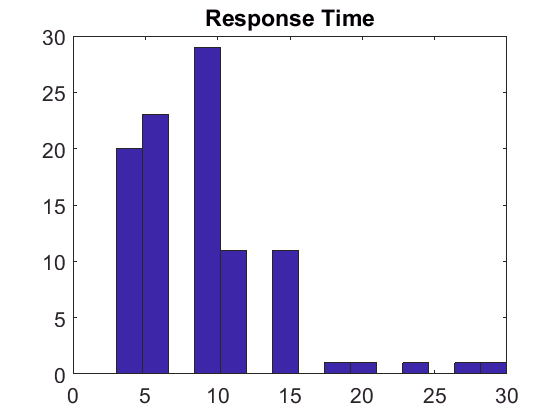


figure
hist(Lags.RT,15);
title('Response Time')

MeanRT = mean(Lags.RT)

MeanRT = 8.8485

SDRT = std(Lags.RT)

SDRT = 5.1851

 Run ANOVA on results to see no dependence on tag

p = 0.0043

tbl = 4×6 cell array
    'Source'    'SS'            'df'    'MS'          'F'         'Prob>F'
    'Groups'    [6.5181e+03]    [23]    [283.3965]    [2.2624]    [0.0043]
    'Error'     [9.3946e+03]    [75]    [125.2614]          []          []
    'Total'     [1.5913e+04]    [98]            []          []          []

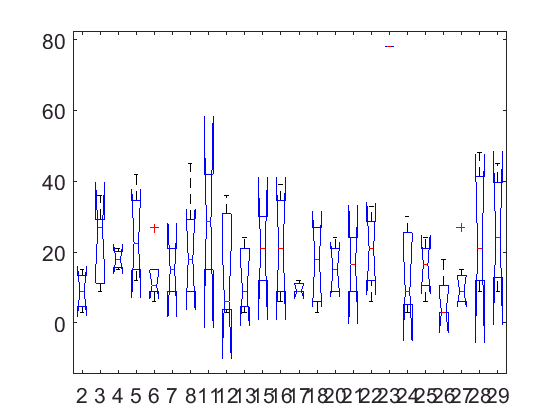

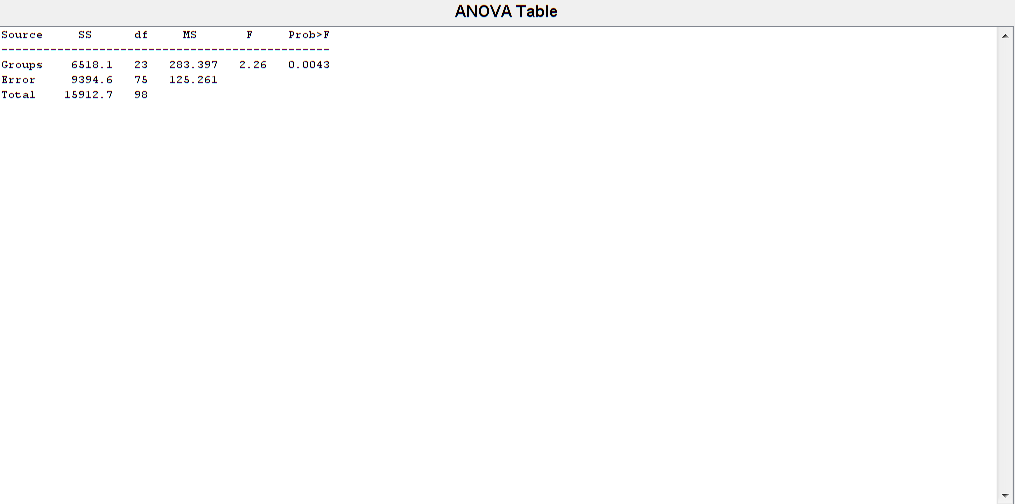

[p,tbl] = anova1(Lags.lag,Lags.tag)

p = 0.1286

tbl = 4×6 cell array
    'Source'    'SS'            'df'    'MS'         'F'         'Prob>F'
    'Groups'    [  800.7844]    [23]    [34.8167]    [1.4238]    [0.1286]
    'Error'     [1.8339e+03]    [75]    [24.4526]          []          []
    'Total'     [2.6347e+03]    [98]           []          []          []

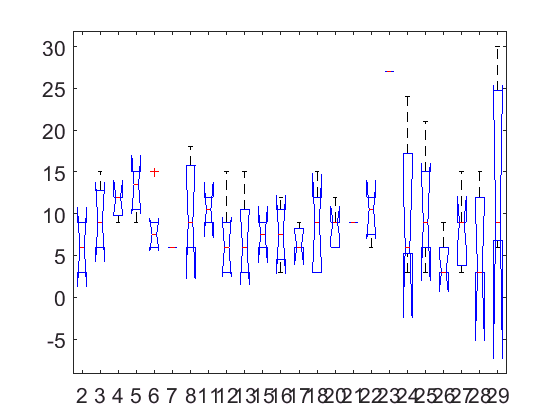

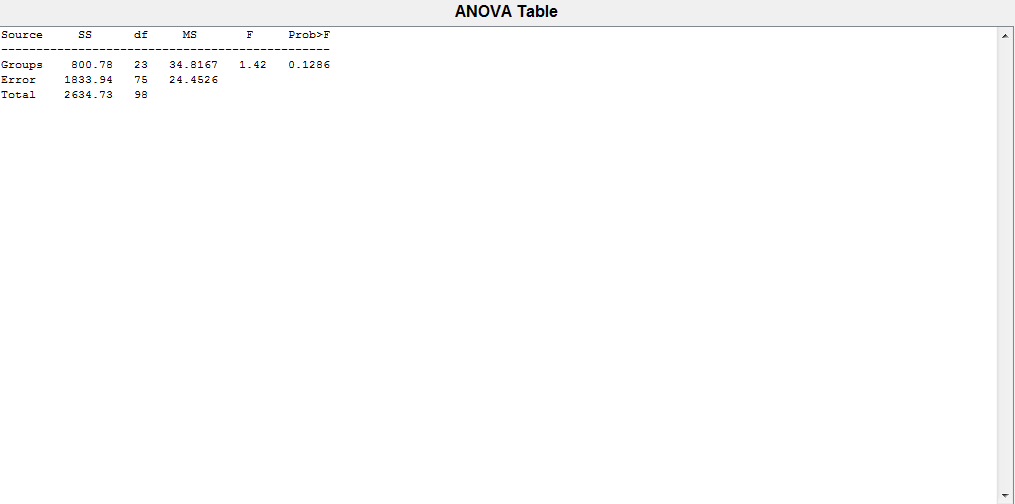


[p,tbl] = anova1(Lags.RT,Lags.tag)

For the lags: got significant difference between groups

For response time, did not.

## Look at correlation btwn dAdt and density

Are the critical high densities followed by the highest digging rates?

If they are, are they proportional to each other?

Also, are those high rates proportional to the number of ants? ** also check this in general for dNdt vs dAdt model (can check just by using maximal dig rates)

Percent = nan(29,1);
for k=UseNests
    tend = find(~isnan(S(k).B.fArea),1,'last');
    t1 = t(t0:tend);
    fA = S(k).B.fArea(t0:tend);
    N = S(k).B.SmoothPop(t0:tend);
    
    H_locs = CritD.locs(CritD.type==1 & CritD.tag==k);
    dAdt = diff(fA)./3;
    Mean_dAdt = mean(dAdt(dAdt>0),'omitnan');
    dAdt_dev = dAdt-repmat(Mean_dAdt,numel(dAdt),1);
    [pks,locs] = findpeaks(dAdt_dev);
    % how many are peaks?
    HowManyArePks = intersect(locs,H_locs)
    Percent(k) = numel(HowManyArePks)./numel(H_locs);
end

HowManyArePks = 16

HowManyArePks =      5
    58

HowManyArePks = 34

HowManyArePks =     30
    56

HowManyArePks =     35
    52

HowManyArePks =
  0×1 empty double column vector


HowManyArePks = 26

HowManyArePks =
  0×1 empty double column vector


HowManyArePks =
  0×1 empty double column vector


HowManyArePks =
  0×1 empty double column vector


HowManyArePks = 10

HowManyArePks = 26

HowManyArePks =
  0×1 empty double column vector


HowManyArePks = 26

HowManyArePks =     19
    23
    52

HowManyArePks = 22

HowManyArePks =
  0×1 empty double column vector


HowManyArePks =
  0×1 empty double column vector


HowManyArePks =
  0×1 empty double column vector


HowManyArePks =
  0×1 empty double column vector


HowManyArePks =
  0×1 empty double column vector


HowManyArePks =
  0×1 empty double column vector


HowManyArePks =
  0×1 empty double column vector


HowManyArePks = 43

HowManyArePks = 13

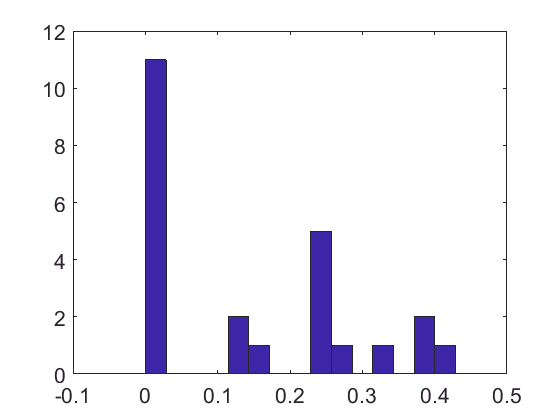

figure
hist(Percent,15)

MeanPercent = mean(Percent,'omitnan')

MeanPercent = 0.1479

SDPercent= std(Percent,'omitnan')

SDPercent = 0.1550

Get low percent of all nests which are peaks (w/ very large SD)

then try different method of checking for distribution of % difference more than median(dAdt) per each nest

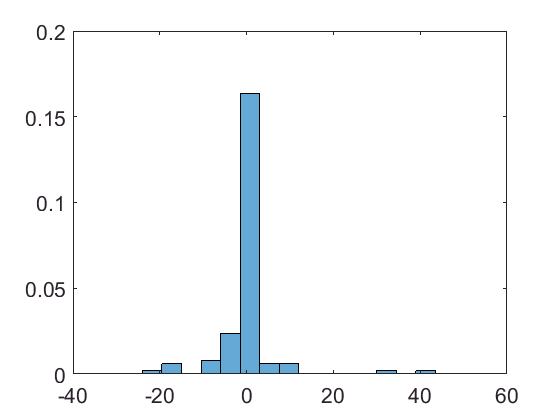

dAdt_dev_m=[];
for k=UseNests
    dAdt = CritD.dAdt(CritD.type==1 & CritD.tag==k);
    Med_dAdt = median(dAdt(dAdt>0),'omitnan');
    dAdt_dev = (dAdt-repmat(Med_dAdt,numel(dAdt),1))./Med_dAdt;
    dAdt_dev(abs(dAdt_dev)>=100)=[]; % filter out more than 100% change outliers
    m = [repmat(k,numel(dAdt_dev),1), dAdt_dev];
    dAdt_dev_m = [dAdt_dev_m; m];
end

figure
histogram(dAdt_dev_m(:,2),25,'Normalization','pdf')

Conclusion: see that not necessarily high digging rate after high critical densities,most are around 0, some even decrease in area (negative rate)

=> look at different cross-correlations maybe

*** need to make plot that shows lack of correlation between the critical high density and immediate dig rate and 

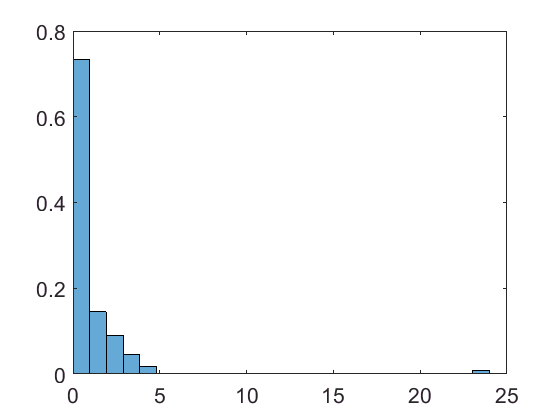

figure
H_dAdt = CritD.dAdt(CritD.type==1);
H_dAdt(H_dAdt<0)=0;
histogram(H_dAdt,25,'Normalization','pdf')

Can see that most (>50%) of points are very close to 0

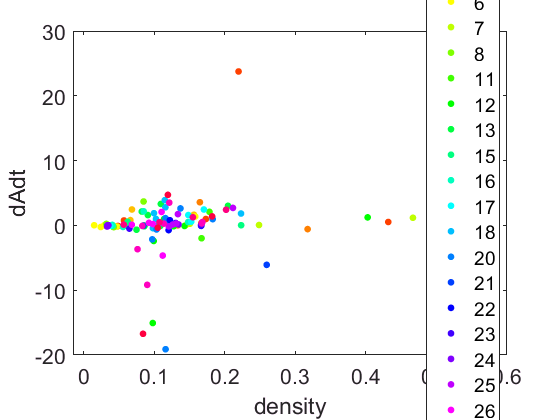

% are they proportional to each other? 
figure
gscatter(CritD.density(CritD.type==1),CritD.dAdt(CritD.type==1),CritD.tag(CritD.type==1))
xlabel('density')
ylabel('dAdt')